# Part 3 : Time and frequency synchronization

In order to receive correctly a signal, there are problems to solve. The time at which the signal arrive is unknown leading to a time $t_0
$ and phase shift $\phi_0
$ of the transmitted signal. In addition due to hardware imperfections on the oscillating crystals and sampler we have sample clock offset $\delta
$ (SCO) and carrier frequency offset $\Delta \omega_$ (CFO). 

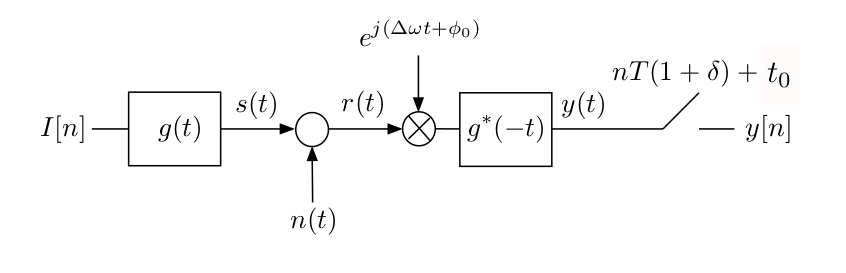

Those errors needs to be modeled. The SCO is neglected and won't be added to the channel. The CFO and phase shift can be added before passing the baseband signal to the matched filter as a multiplication by an exponential $e^{j\left(\Delta\omega t+\phi_0\right)
$ The CFO will create ISI since the matched filter is frequency shifted and therefore not matched anymore.The phase shift will rotate the the symbol which will no longer be demapped correctly.

The next function will do the multiplication of $r(t)
$ by the complex exponential  $e^{j\left(\Delta\omega t+\phi_0\right)
$

clc; close all; clear all;
addpath("C:\Users\François\Downloads\MA1\MC\project\ELEC-H-401-DVB-S2\1 Optimal communication chain over the ideal channel");

Nbit = 1800;
Nbps = 1;    %Nombre of bits per symbol (1 = BPSK, 2 = 4QAM, 4 = 16QAM, 6 = 64QAM)
f_cut = 1e6; %Hz Cutoff frequency
fsymb = 2*f_cut;
T_symb = 1/fsymb;
fsamp = 8*fsymb; % Sampling frequency (rule of thumb for the 10 25 times f_cut) Its the freq on which the conv of the filter and the signal will be done --> has to be the same !!!
M = 16; %Upsampling factor (au moins plus grand que 4)
EbNo = 20; %Energy of one by over the PSD of the noise ratio (in dB)
N_taps = 101; %number of taps of the filter
beta = 0.3; %Makes the window smoother as beta increases // roll-off factor given in the specifications
%% Bit Generator

bits = randi(2,1,Nbit)-1;
check_mult = mod(Nbit,Nbps);
if check_mult == 0
    bit_tx = bits;
else
    bit_tx = [bits  zeros(1,Nbps - check_mult)];
end
Nbit_tx = length(bit_tx);

%% Mapping
%Maps the bits into desired symbols in the complex plane 
if (Nbps > 1)
    symb_tx = mapping(bit_tx', Nbps, 'qam')';
else
    symb_tx = mapping(bit_tx', Nbps, 'pam')';
end

%figure(12); grid on; title("Mapped signal in absolute value"); stem(abs(symb_tx));
%% Upsampling

upsampled_symb_tx = UpSampling(symb_tx,Nbit_tx,Nbps,M);


%% Transmitter Filter

filter = HalfrootNyquistFilter(fsamp,T_symb,N_taps); %So we compute de filter only 1 time as this is the same

signal_tx = conv(upsampled_symb_tx,filter);%Convolution of the signal with the filter
signal_tx1 = conv(upsampled_symb_tx(1:M),filter);


%figure(7); stem(abs(signal_tx)); title("transmited signal")
%signal_tx = upsampled_symb_tx;


%% Transmission Channel

%signal_rx = NoiseAddition(signal_tx,EbNo,fsamp,Nbit);      %With Noise
signal_rx = signal_tx;                              %Without Nosie

% signal_rx1 = NoiseAddition(signal_tx1,EbNo,fsamp,Nbps);      %With Noise
signal_rx1 = signal_tx1;      %With Noise

%fig_signal_tx = figure('Name','signal_tx','NumberTitle','off');plot(signal_rx,'b.');grid on;hold on;plot(signal_tx,'ro');

Here we add the CFO and phase shift

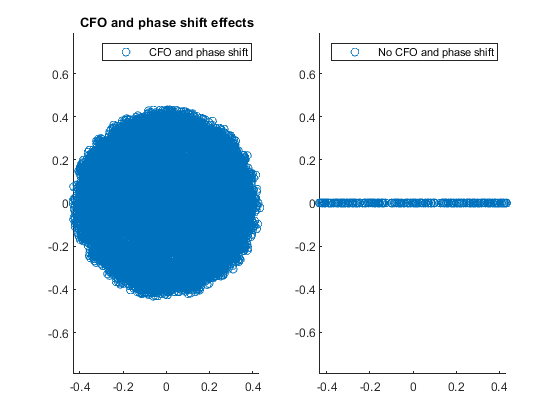

fs_passband= 2e9; %Hz
CFO = 2; % CFO in ppm (2 to see something)
CFO = fs_passband*CFO*1e-6; %CFO in Hz
[signal_rx_CFO, phase_shift] = Add_CFO_and_phase_shift(signal_rx,CFO,fsamp);
figure;subplot(1,2,1); scatter(real(signal_rx_CFO),imag(signal_rx_CFO)); axis equal; title("CFO and phase shift effects"); legend("CFO and phase shift"); subplot(1,2,2); scatter(real(signal_rx),imag(signal_rx)); axis equal; legend( "No CFO and phase shift");

We see the rotation due to the phase shift. The ISI will be shown later.

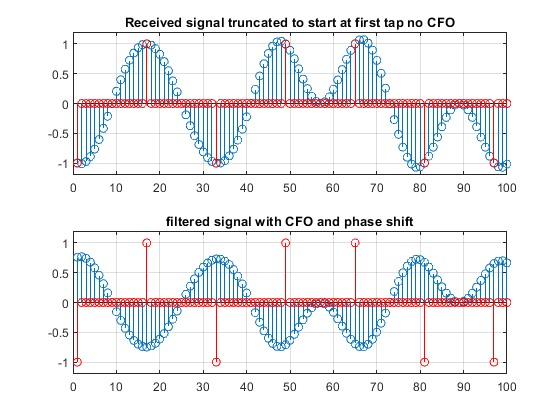

%% Receiver Filter
matched_filter = flip(filter); %Get the time reversal of the filter g(-t) 
upsampled_symb_rx_CFO = conv(signal_rx_CFO,matched_filter,'valid'); %Matched filter convolved with the signal; 'valid' to remove padded zeroes added by the convolution
upsampled_symb_rx = conv(signal_rx,matched_filter,'valid');
upsampled_symb_rx1 = conv(signal_rx1,matched_filter); upsampled_symb_rx1 = upsampled_symb_rx1(N_taps:end-(N_taps-1)+1);

figure(9);subplot(2,1,1);stem(real(upsampled_symb_rx)); hold on; stem(real(upsampled_symb_tx),'r'); title("Received signal truncated to start at first tap no CFO"); grid on; subplot(2,1,2); stem(real(upsampled_symb_rx_CFO));hold on; stem(real(upsampled_symb_tx),'r'); title("filtered signal with CFO and phase shift");grid on;

subplot(2,1,1)
xlim([0 100])
ylim([-1.2 1.2])
subplot(2,1,2)
xlim([0 100])
ylim([-1.2 1.2])

The ISI is clearly visible in the subplot with CFO.

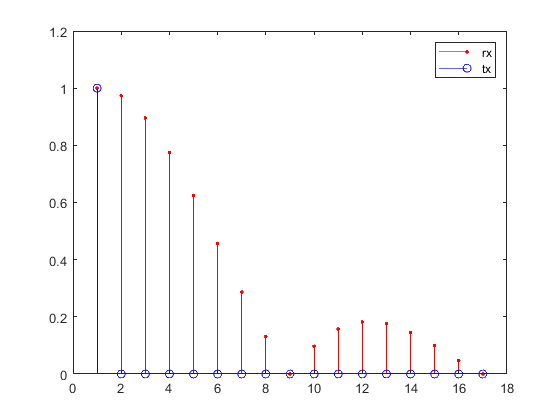

figure;grid on;title("Upsampled 1st Symbols without Noise"); 
stem(abs(upsampled_symb_rx1),'r.');hold on; stem([abs(upsampled_symb_tx(1:M)) 0],'bo');legend('rx','tx');

Now it is time to had the time shift at the analog to digital converter. The time shift can vary but should be less than a symbol period.

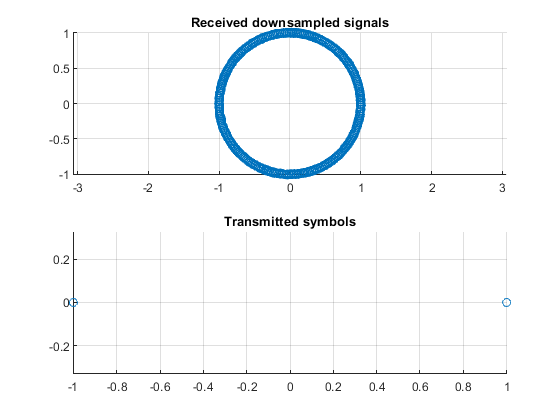

%% Downsampling
%sampling_time_shift = round(rand(1)*M/Nbps); %There is 1 symbol every M/Npbs index
sampling_time_shift = 0;
symb_rx = DownSampling(upsampled_symb_rx_CFO,Nbit_tx,Nbps,M,sampling_time_shift);

figure(10); grid on;subplot(2,1,1); scatter(real(symb_rx),imag(symb_rx)); axis equal;grid on; title("Received downsampled signals"); subplot(2,1,2); scatter(real(symb_tx),imag(symb_tx));axis equal; title("Transmitted symbols");grid on;

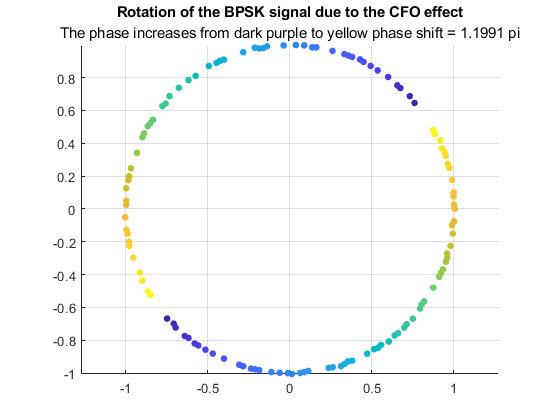

plotted_points= 120;
c = linspace(1,plotted_points,plotted_points); %From dark purple to yellow
figure; scatter(real(symb_rx(1:plotted_points)),imag(symb_rx(1:plotted_points)),25,c,'filled'); axis equal;grid on; title("Rotation of the BPSK signal due to the CFO effect"); subtitle("The phase increases from dark purple to yellow phase shift = "+ string(phase_shift/pi)+" pi")%hold on; scatter(real(symb_rx(end-10:end)),imag(symb_rx(end-10:end)),'r*'); %hold on; scatter(real(symb_rx(101:150)),imag(symb_rx(101:150)),'yd'); axis equal;grid on; %subplot(1,4,4); scatter(real(symb_rx(end-200:end)),imag(symb_rx(end-200:end))); axis equal;grid on;

%% Demapping
 
if (Nbps > 1)
    bit_rx = demapping(symb_rx', Nbps, 'qam')';
else
    bit_rx = demapping(real(symb_rx)', Nbps, 'pam')';
end

bit_down_scaled = bit_rx(1:Nbit);


%% Bits check

ErrorRatio = ErrorCalculator(bit_rx,bit_tx)

ErrorRatio = 0.5056